clc; clear; close all;

% Cargar datos
data = readtable('Five_times_Kinematics_HT_Query_final.xlsx');

fprintf('Dimensiones del dataset: %d filas x %d columnas\n', size(data,1), size(data,2));

Dimensiones del dataset: 46 filas x 81 columnas


disp('Variables del dataset:');

Variables del dataset:


disp(data.Properties.VariableNames);

    {'reclutado'}    {'AgeGroup'}    {'BMI_Value'}    {'GroupName'}    {'x1_AAFEM'}    {'x2_AAFEM'}    {'x4_AAFEM'}    {'x5_AAFEM'}    {'x1_AAIEM'}    {'x2_AAIEM'}    {'x3_AAIEM'}    {'x4_AAIEM'}    {'x5_AAIEM'}    {'x2_AKFEM'}    {'x3_AKFEM'}    {'x4_AKFEM'}    {'x5_AKFEM'}    {'x1_AKAAM'}    {'x2_AKAAM'}    {'x3_AKAAM'}    {'x4_AKAAM'}    {'x1_AKIEM'}    {'x2_AKIEM'}    {'x3_AKIEM'}    {'x4_AKIEM'}    {'x5_AKIEM'}    {'x1_AHPFEM'}    {'x2_AHPFEM'}    {'x3_AHPFEM'}    {'x4_AHPFEM'}    {'x5_AHPFEM'}    {'x2_AHPAAM'}    {'x3_AHPAAM'}    {'x4_AHPAAM'}    {'x5_AHPAAM'}    {'x1_AHPIEM'}    {'x3_AHPIEM'}    {'x4_AHPIEM'}    {'x5_AHPIEM'}    {'x1_APTILTM'}    {'x2_APTILTM'}    {'x3_APTILTM'}    {'x4_APTILTM'}    {'x5_APTILTM'}    {'x1_APOBLIM'}    {'x2_APOBLIM'}    {'x3_APOBLIM'}    {'x4_APOBLIM'}    {'x1_APROTM'}    {'x2_APROTM'}    {'x3_APROTM'}    {'x4_APROTM'}    {'x5_APROTM'}    {'x1_ASPMLM'}    {'x2_ASPMLM'}    {'x3_ASPMLM'}    {'x4_ASPMLM'}    {'x5_ASPMLM'}    {'x2_ASPIEM'}    {'x3_AS


% Seleccionar columnas numéricas
isNum = varfun(@isnumeric, data, 'OutputFormat','uniform');
numericData = data(:, isNum);
X = table2array(numericData);
[n, p] = size(X);
fprintf('El dataset sin outliers tiene %d muestras y %d dimensiones.\n', n, p);

El dataset sin outliers tiene 46 muestras y 78 dimensiones.


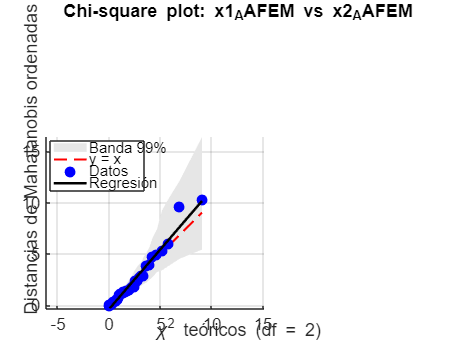

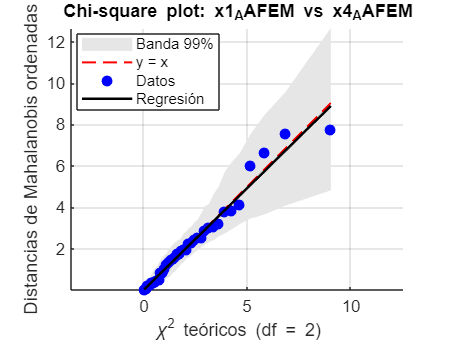

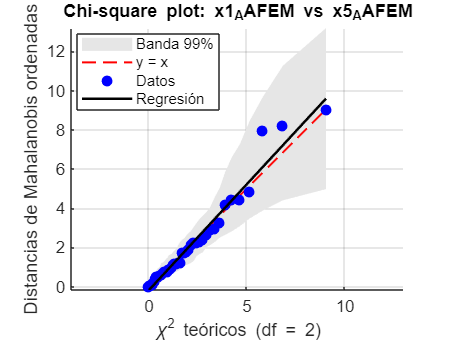

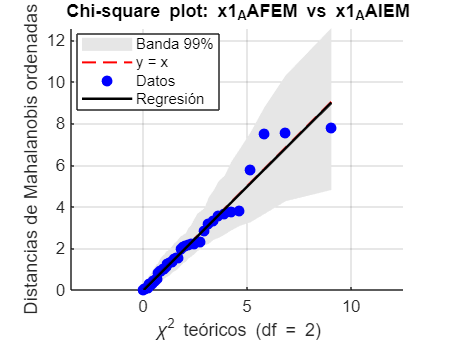

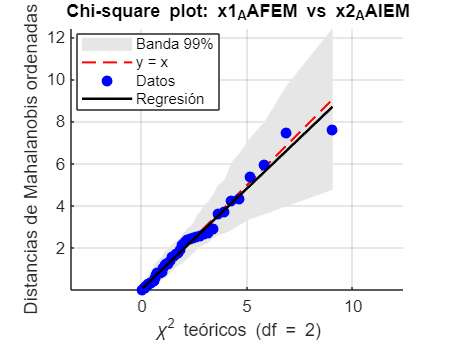

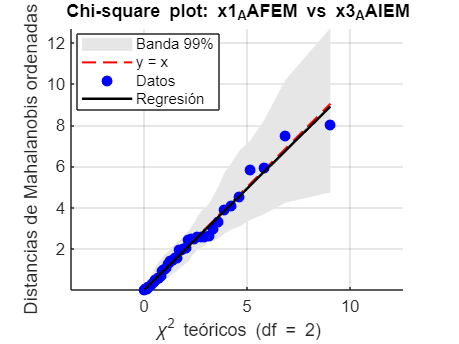

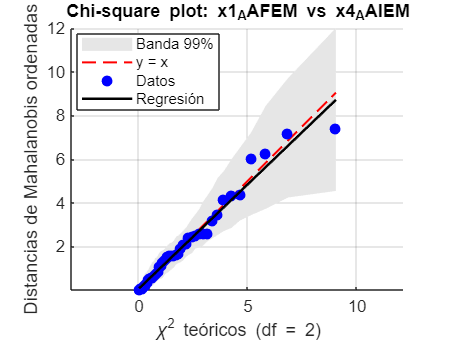

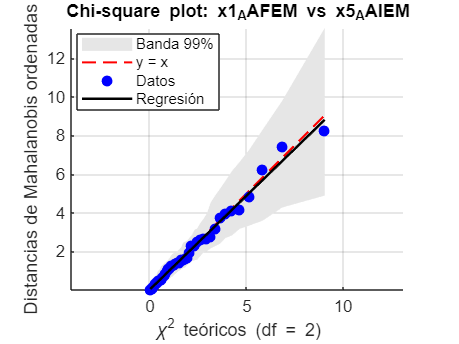


% Parámetros
B = 1000;
alpha = 0.01;
lower_p = alpha/2;
upper_p = 1 - alpha/2;
dim_interes = 2;

% Listas para resultados
var_names = {}; slope_vals = []; R2_vals = [];
slope_pval = []; R2_pval = [];

for j = 3:p
    X_sub = [X(:, dim_interes), X(:, j)];
    mean_vec = mean(X_sub);
    cov_mat = cov(X_sub);
    inv_cov = pinv(cov_mat);

    % Distancias de Mahalanobis
    D2_obs = zeros(n,1);
    for i = 1:n
        d = X_sub(i,:) - mean_vec;
        D2_obs(i) = d * inv_cov * d';
    end
    D2_obs_sorted = sort(D2_obs);
    chi2_q = chi2inv(((1:n)' - 0.5) / n, 2);

    % Banda de confianza bootstrap
    D2_boot = zeros(n, B);
    for b = 1:B
        idx = randi(n, n, 1);
        Xb = X_sub(idx, :);
        mean_b = mean(Xb);
        cov_b = cov(Xb);
        inv_cov_b = pinv(cov_b);
        db_mat = Xb - mean_b;
        D2b = sum((db_mat * inv_cov_b) .* db_mat, 2);
        D2_boot(:,b) = sort(D2b);
    end
    lower_env = quantile(D2_boot, lower_p, 2);
    upper_env = quantile(D2_boot, upper_p, 2);

    % Ajuste original
    coeffs = polyfit(chi2_q, D2_obs_sorted, 1);
    y_fit = polyval(coeffs, chi2_q);
    R2 = corr(chi2_q, D2_obs_sorted)^2;
    m_obs = coeffs(1);

    % Bootstrap para pendiente y R²
    boot_slopes = zeros(B,1);
    boot_R2 = zeros(B,1);
    for b = 1:B
        idx = randsample(n, n, true);
        x_boot = chi2_q(idx);
        y_boot = D2_obs_sorted(idx);
        c = polyfit(x_boot, y_boot, 1);
        boot_slopes(b) = c(1);
        boot_R2(b) = corr(x_boot, y_boot)^2;
    end

    % p-valores para tests bilaterales respecto a valor 1
    p_slope = mean(abs(boot_slopes - 1) >= abs(m_obs - 1));
    p_r2 = mean(abs(boot_R2 - 1) >= abs(R2 - 1));

    % Guardar resultados
    var_i = numericData.Properties.VariableNames{dim_interes};
    var_j = numericData.Properties.VariableNames{j};
    var_names{end+1} = sprintf('%s vs %s', var_i, var_j);
    slope_vals(end+1) = m_obs;
    R2_vals(end+1) = R2;
    slope_pval(end+1) = p_slope;
    R2_pval(end+1) = p_r2;

    % Gráfico
    figure;
    hold on;
    fill([chi2_q; flipud(chi2_q)], ...
         [lower_env; flipud(upper_env)], ...
         [0.9 0.9 0.9], 'EdgeColor','none');
    plot(chi2_q, chi2_q, 'r--', 'LineWidth',1.2);
    plot(chi2_q, D2_obs_sorted, 'bo', 'MarkerFaceColor','b');
    plot(chi2_q, y_fit, 'k-', 'LineWidth', 1.5);
    hold off;
    axis equal; grid on;
    xlabel('\chi^2 teóricos (df = 2)');
    ylabel('Distancias de Mahalanobis ordenadas');
    title(sprintf('Chi-square plot: %s vs %s', var_i, var_j));
    legend('Banda 99%', 'y = x', 'Datos', 'Regresión', 'Location', 'best');
end


% Crear tabla de resultados
tabla_resultados = table(var_names', slope_vals', slope_pval', R2_vals', R2_pval', ...
    'VariableNames', {'Comparación', 'Pendiente', 'p_Pendiente≠1', 'R2', 'p_R2≠1'});

% Mostrar tabla
disp('============================================');

disp('>> Resultados con test bootstrap sobre pendiente y R²:');

>> Resultados con test bootstrap sobre pendiente y R²:


disp(tabla_resultados);

             Comparación              Pendiente    p_Pendiente≠1      R2       p_R2≠1
    ______________________________    _________    _____________    _______    ______

    {'x1_AAFEM vs x2_AAFEM'      }      1.1643         0.471        0.96732    0.434 
    {'x1_AAFEM vs x4_AAFEM'      }     0.98305         0.805        0.97267    0.284 
    {'x1_AAFEM vs x5_AAFEM'      }      1.0814         0.483        0.96717    0.428 
    {'x1_AAFEM vs x1_AAIEM'      }     0.99769         0.974        0.96093    0.347 
    {'x1_AAFEM vs x2_AAIEM'      }      0.9549         0.499        0.98055    0.296 
    {'x1_AAFEM vs x3_AAIEM'      }     0.98516         0.776        0.98246     0.31 
    {'x1_AAFEM vs x4_AAIEM'      }     0.95799          0.63        0.97239     0.34 
    {'x1_AAFEM vs x5_AAIEM'      }     0.97064         


% Dividir tabla según umbral de R²
R2_threshold = 0.9632;
tabla_R2_alto = tabla_resultados(tabla_resultados.R2 >= R2_threshold, :);
tabla_R2_bajo = tabla_resultados(tabla_resultados.R2 < R2_threshold, :);

% Mostrar resultados divididos
disp('============================================');

fprintf('>> Comparaciones con R² >= %.4f:\n', R2_threshold);

>> Comparaciones con R² >= 0.9632:


disp(tabla_R2_alto);

             Comparación              Pendiente    p_Pendiente≠1      R2       p_R2≠1
    ______________________________    _________    _____________    _______    ______

    {'x1_AAFEM vs x2_AAFEM'      }      1.1643         0.471        0.96732    0.434 
    {'x1_AAFEM vs x4_AAFEM'      }     0.98305         0.805        0.97267    0.284 
    {'x1_AAFEM vs x5_AAFEM'      }      1.0814         0.483        0.96717    0.428 
    {'x1_AAFEM vs x2_AAIEM'      }      0.9549         0.499        0.98055    0.296 
    {'x1_AAFEM vs x3_AAIEM'      }     0.98516         0.776        0.98246     0.31 
    {'x1_AAFEM vs x4_AAIEM'      }     0.95799          0.63        0.97239     0.34 
    {'x1_AAFEM vs x5_AAIEM'      }     0.97064         0.584        0.98831    0.321 
    {'x1_AAFEM vs x2_AKFEM'      }     0.97798         


fprintf('\n>> Comparaciones con R² < %.4f:\n', R2_threshold);


>> Comparaciones con R² < 0.9632:


disp(tabla_R2_bajo);

             Comparación              Pendiente    p_Pendiente≠1      R2       p_R2≠1
    ______________________________    _________    _____________    _______    ______

    {'x1_AAFEM vs x1_AAIEM'      }     0.99769         0.974        0.96093    0.347 
    {'x1_AAFEM vs x4_AKFEM'      }      1.0195         0.819        0.94274    0.307 
    {'x1_AAFEM vs x2_AKAAM'      }       1.086         0.524        0.96298    0.449 
    {'x1_AAFEM vs x5_AKIEM'      }      1.0087         0.887        0.95746    0.412 
    {'x1_AAFEM vs x4_AHPFEM'     }      1.0579         0.619        0.96174     0.31 
    {'x1_AAFEM vs x3_ASHOBLIOFFM'}      1.0743         0.501        0.96125    0.415 
    {'x1_AAFEM vs x4_ASHROTOFFM' }      1.1166         0.489        0.96256    0.381 
    {'x1_AAFEM vs x5_ASHROTOFFM' }      1.1641         